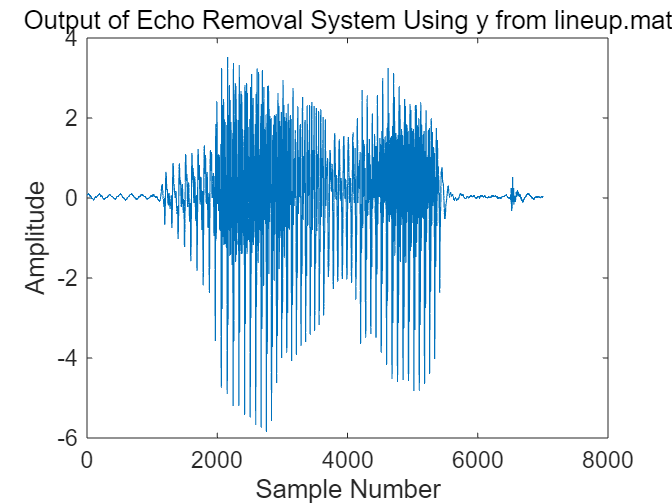

% 加载数据
load('lineup.mat'); % 确保文件名和路径正确
% 假定的参数
N = 1000;
alpha = 0.5;
% 假设我们使用 y 向量作为输入信号
input_signal = y; % 假设y是7000x1的double向量
% 初始化输出信号向量
output_signal = zeros(size(input_signal));
% 应用回声消除系统方程
% z[n] + αz[n - N] = y[n]
output_signal(1:N) = input_signal(1:N); % 初始化前N个样本
for n = N+1:length(input_signal)
output_signal(n) = input_signal(n) - alpha * output_signal(n - N);
end
% 可视化输出信号
figure;
plot(output_signal);
title('Output of Echo Removal System Using y from lineup.mat');
xlabel('Sample Number');
ylabel('Amplitude');